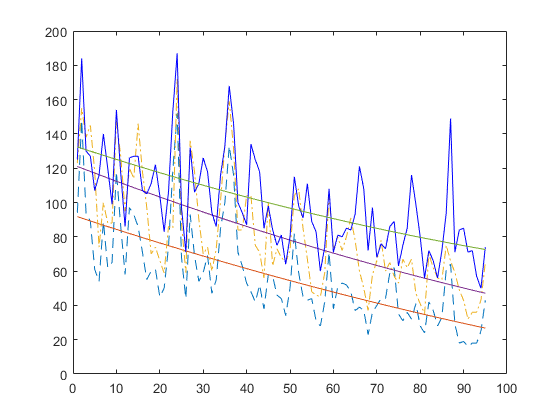

clc;
clear;
close all;
[file,path] = uigetfile({'*.xlsx';'*.xls'},'File Selector');
filepath=strcat(path,file);
XJData = xlsread(filepath);


X1 =XJData(:,3);

numsize = size (X1);
numsize = numsize(1);

Xp1 = X1(1:numsize);

plot(X1,'--')
hold('on');

timelong = 1:numsize;
timelong =timelong';

p = polyfit(timelong,X1,2);
plot(polyval(p,timelong))
hold('on');


X2 =XJData(:,4);
Xp2 = X2(1:numsize);
plot(X2,'-.')
hold('on');

p = polyfit(timelong,X2,2);
plot(polyval(p,timelong))
hold('on');

X3 =XJData(:,5);
Xp3 = X3(1:numsize);
plot(X3,'b')
hold('on');

p = polyfit(timelong,X3,2);
plot(polyval(p,timelong))
hold('on');





% ten1 = flip(Xp1);
% ten2 = flip(Xp2);
% ten3 = flip(Xp3);
% tennum = 1:12;
% ten1 = ten1(tennum);
% ten2 = ten2(tennum);
% ten3 = ten3(tennum);


% [Xp1,cp1,errorp1,errorp2]=GM11(ten1,3);
% scalength=1:3;
% plot(scalength,Xp1(13:15));
% hold on;
% 
% [Xp2,cp1,errorp1,errorp2]=GM11(ten2,3);
% 
% plot(scalength,Xp2(13:15));
% hold on;
% 
% [Xp3,cp1,errorp1,errorp2]=GM11(ten3,3);

% plot(scalength,Xp3(13:15));
% hold on;
% title("未来三个月发展趋势")
% legend('预测PM2.5趋势','预测PM10趋势','预测AQI趋势');
% 
% 
% Date = 1:3;
% 
% Xs = [Date' Xp1(13:15)' Xp2(13:15)' Xp3(13:15)'];
% 
% Xs = flipud(Xs);
% app.UITable.Data =Xs;
% legend(app.forecasteplot,'PM2.5值','PM2.5趋势','PM10值','PM10趋势','AQI值','AQI趋势');


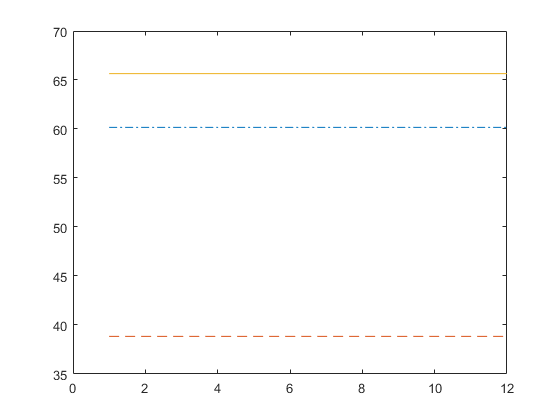

trainX=1:numsize;
% trainX = trainX';
trainY=[Xp1,Xp2,Xp3];
trainY = trainY';

[trainX,p]=mapminmax(trainX);
[trainY,q]=mapminmax(trainY);

net = newff(trainX, trainY,[5 5]);
net.trainParam.lr = 0.02;%0.02
net.trainParam.epochs = 25;%500,5000
net.trainParam.goal = 0.00001;
net = train(net,trainX,trainY);
%训练数据预测
BPoutput=sim(net,trainX);
BPoutput=mapminmax('reverse',BPoutput,q);

Days = numsize+1:(numsize + 3);
BPDays=sim(net,Days);
BPDays=mapminmax('reverse',BPDays,q);
BPDays =BPDays';
figure;
plot(BPDays(:,1),'-.');
hold on;
plot(BPDays(:,2),'--');
hold on;
plot(BPDays(:,3));
hold on;

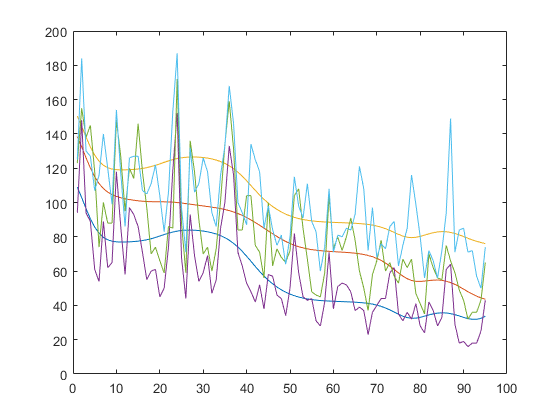


%预测误差
erroryc=trainY-BPoutput;
BPoutput = BPoutput';
figure;
plot(BPoutput(:,1))
hold on;
plot(BPoutput(:,2))
hold on;
plot(BPoutput(:,3))
hold on;

plot(X1)
hold on;
plot(X2)
hold on;
plot(X3)
hold on;